# Using some simple Parallel computing commands

## 0. Introduction

This tutorial aims to help biomedical students and researchers do some basic image analysis and help them make use simple parallel computing commands using MATLAB. After this tutorial, one should be able to

- Handle video files

- Segment images from video files.

- Speed up repetitive tasks (parallel for loop) on your computer

- Run a code in the background (submit a job) without blocking MATLAB

To be able to run this tutorial, the [Image Proceessing Toolbox](https://www.mathworks.com/products/image.html) and the [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html) is required. If there is no MATLAB license available, a free trial here can be [downloaded here](https://www.mathworks.com/campaigns/products/trials.html).

### Further learning

Additional resources related to biomedical image processing applications with MATLAB 

- [Get Started with Image Processing Toolbox](https://www.mathworks.com/help/images/getting-started-with-image-processing-toolbox.html)

- [Hands-on Image Processing Tutorial](https://www.mathworks.com/learn/tutorials/image-processing-onramp.html)

- Other Projects on Medical Image Processing on [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange?q=medical+image+processing) 

- [Get Started with Parallel Computing Toolbox](https://www.mathworks.com/help/parallel-computing/getting-started-with-parallel-computing-toolbox.html)

Some house-keeping at the beginning

% To erase all previous variables from MATLAB's memory 
clear all 

% To close all previous figures
close all 

% To clear the screen
clc 

% To add the path of files that we need
addpath('Required files/')

## 1. Extract images from a video

- Previewing the video. Courtsey of [http://www.cellimagelibrary.org/images/12608](http://www.cellimagelibrary.org/images/12608) 

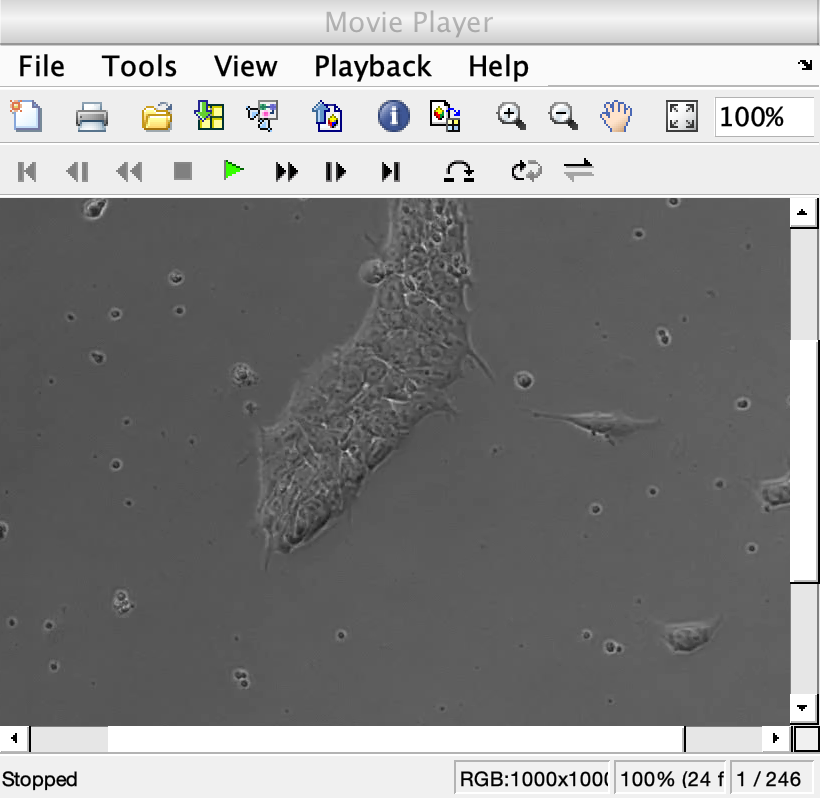

video_filename = 'stem_cell_migration.mp4';
implay(video_filename)

- Save the images

Create a video reader object using the function [`VideoReader`](https://www.mathworks.com/help/matlab/ref/videoreader.html)`. `Read frames using [`read`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.read.html) method.  Use [`imwrite`](https://www.mathworks.com/help/matlab/ref/imwrite.html) to save each frame into the `image_files` directory using a [`for loop`](https://www.mathworks.com/help/matlab/ref/for.html).

video = VideoReader(video_filename);

new_folder = 'Required files/image_files';
mkdir(new_folder);

tic
for i = 1:video.NumFrames
    frame = read(video,i);
    imwrite(frame, [new_folder,'/frame',num2str(i,'%03d'),'.tif'])
end
toc

Elapsed time is 3.233161 seconds.


## **2. Starting a parallel 'pool' on ****my**** computer. **

A parallel pool is a set of MATLAB workers on a compute cluster or desktop. 

A MATLAB Worker is a MATLAB computational engine that runs in the background without a graphical desktop.

It is also good to know about core, CPU, GPU and Node. To read more about the basics of parallel computing in brief visit [What is parallel computing?](https://www.mathworks.com/help/parallel-computing/what-is-parallel-computing.html)

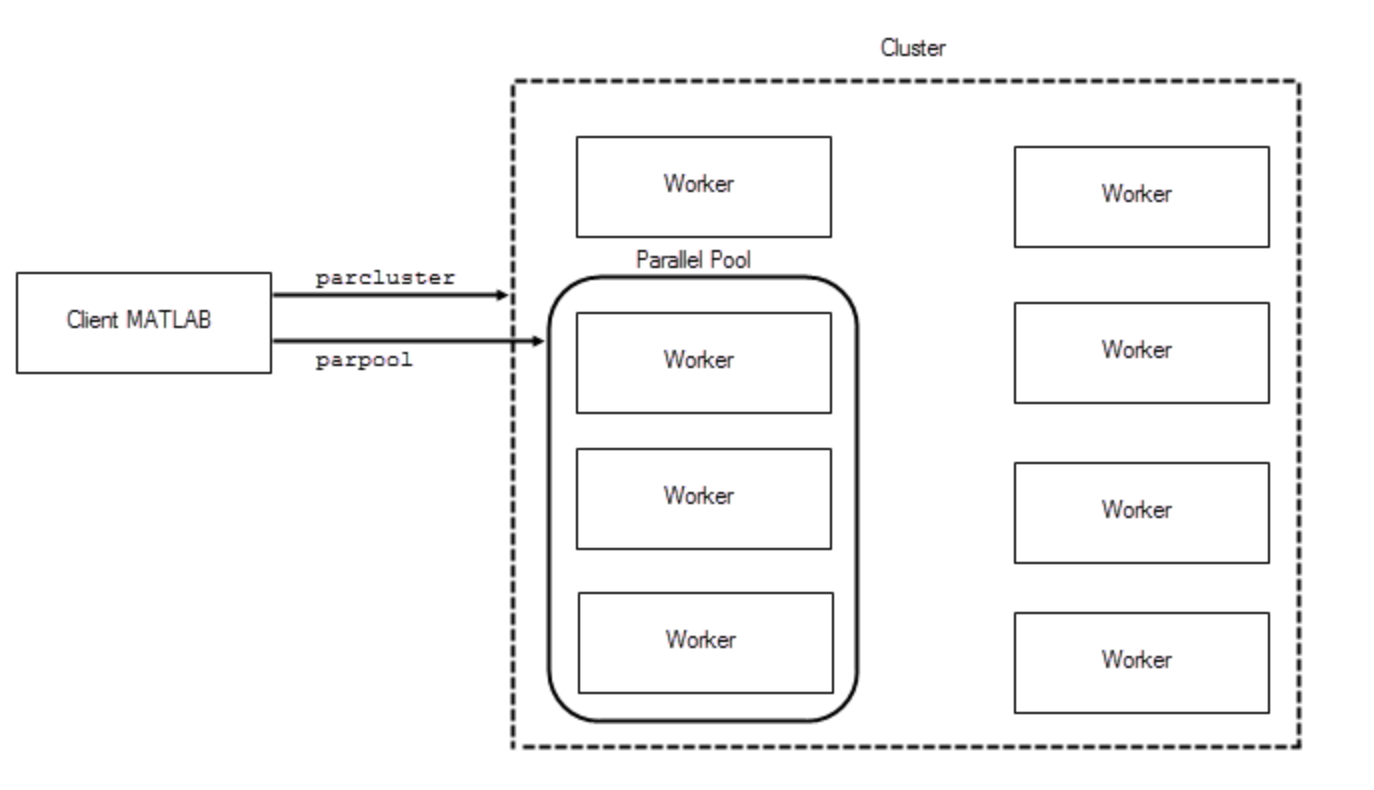

The default cluster profile is saved in 'local'. 

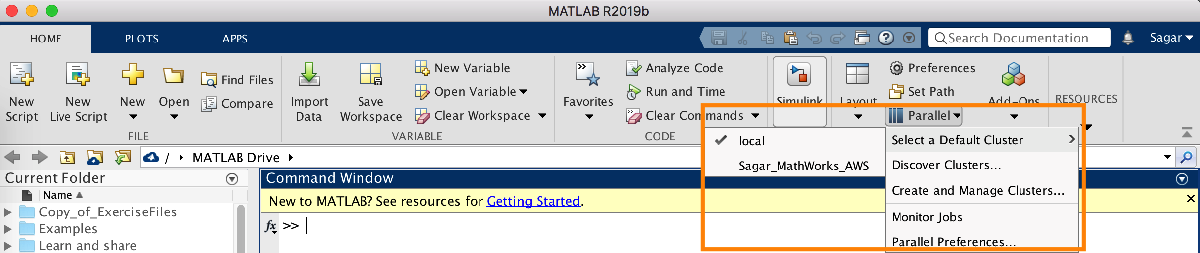

You can also change the properties of the default profile by going to Parallel -> Create and Manage Clusters.... as shown in the image below

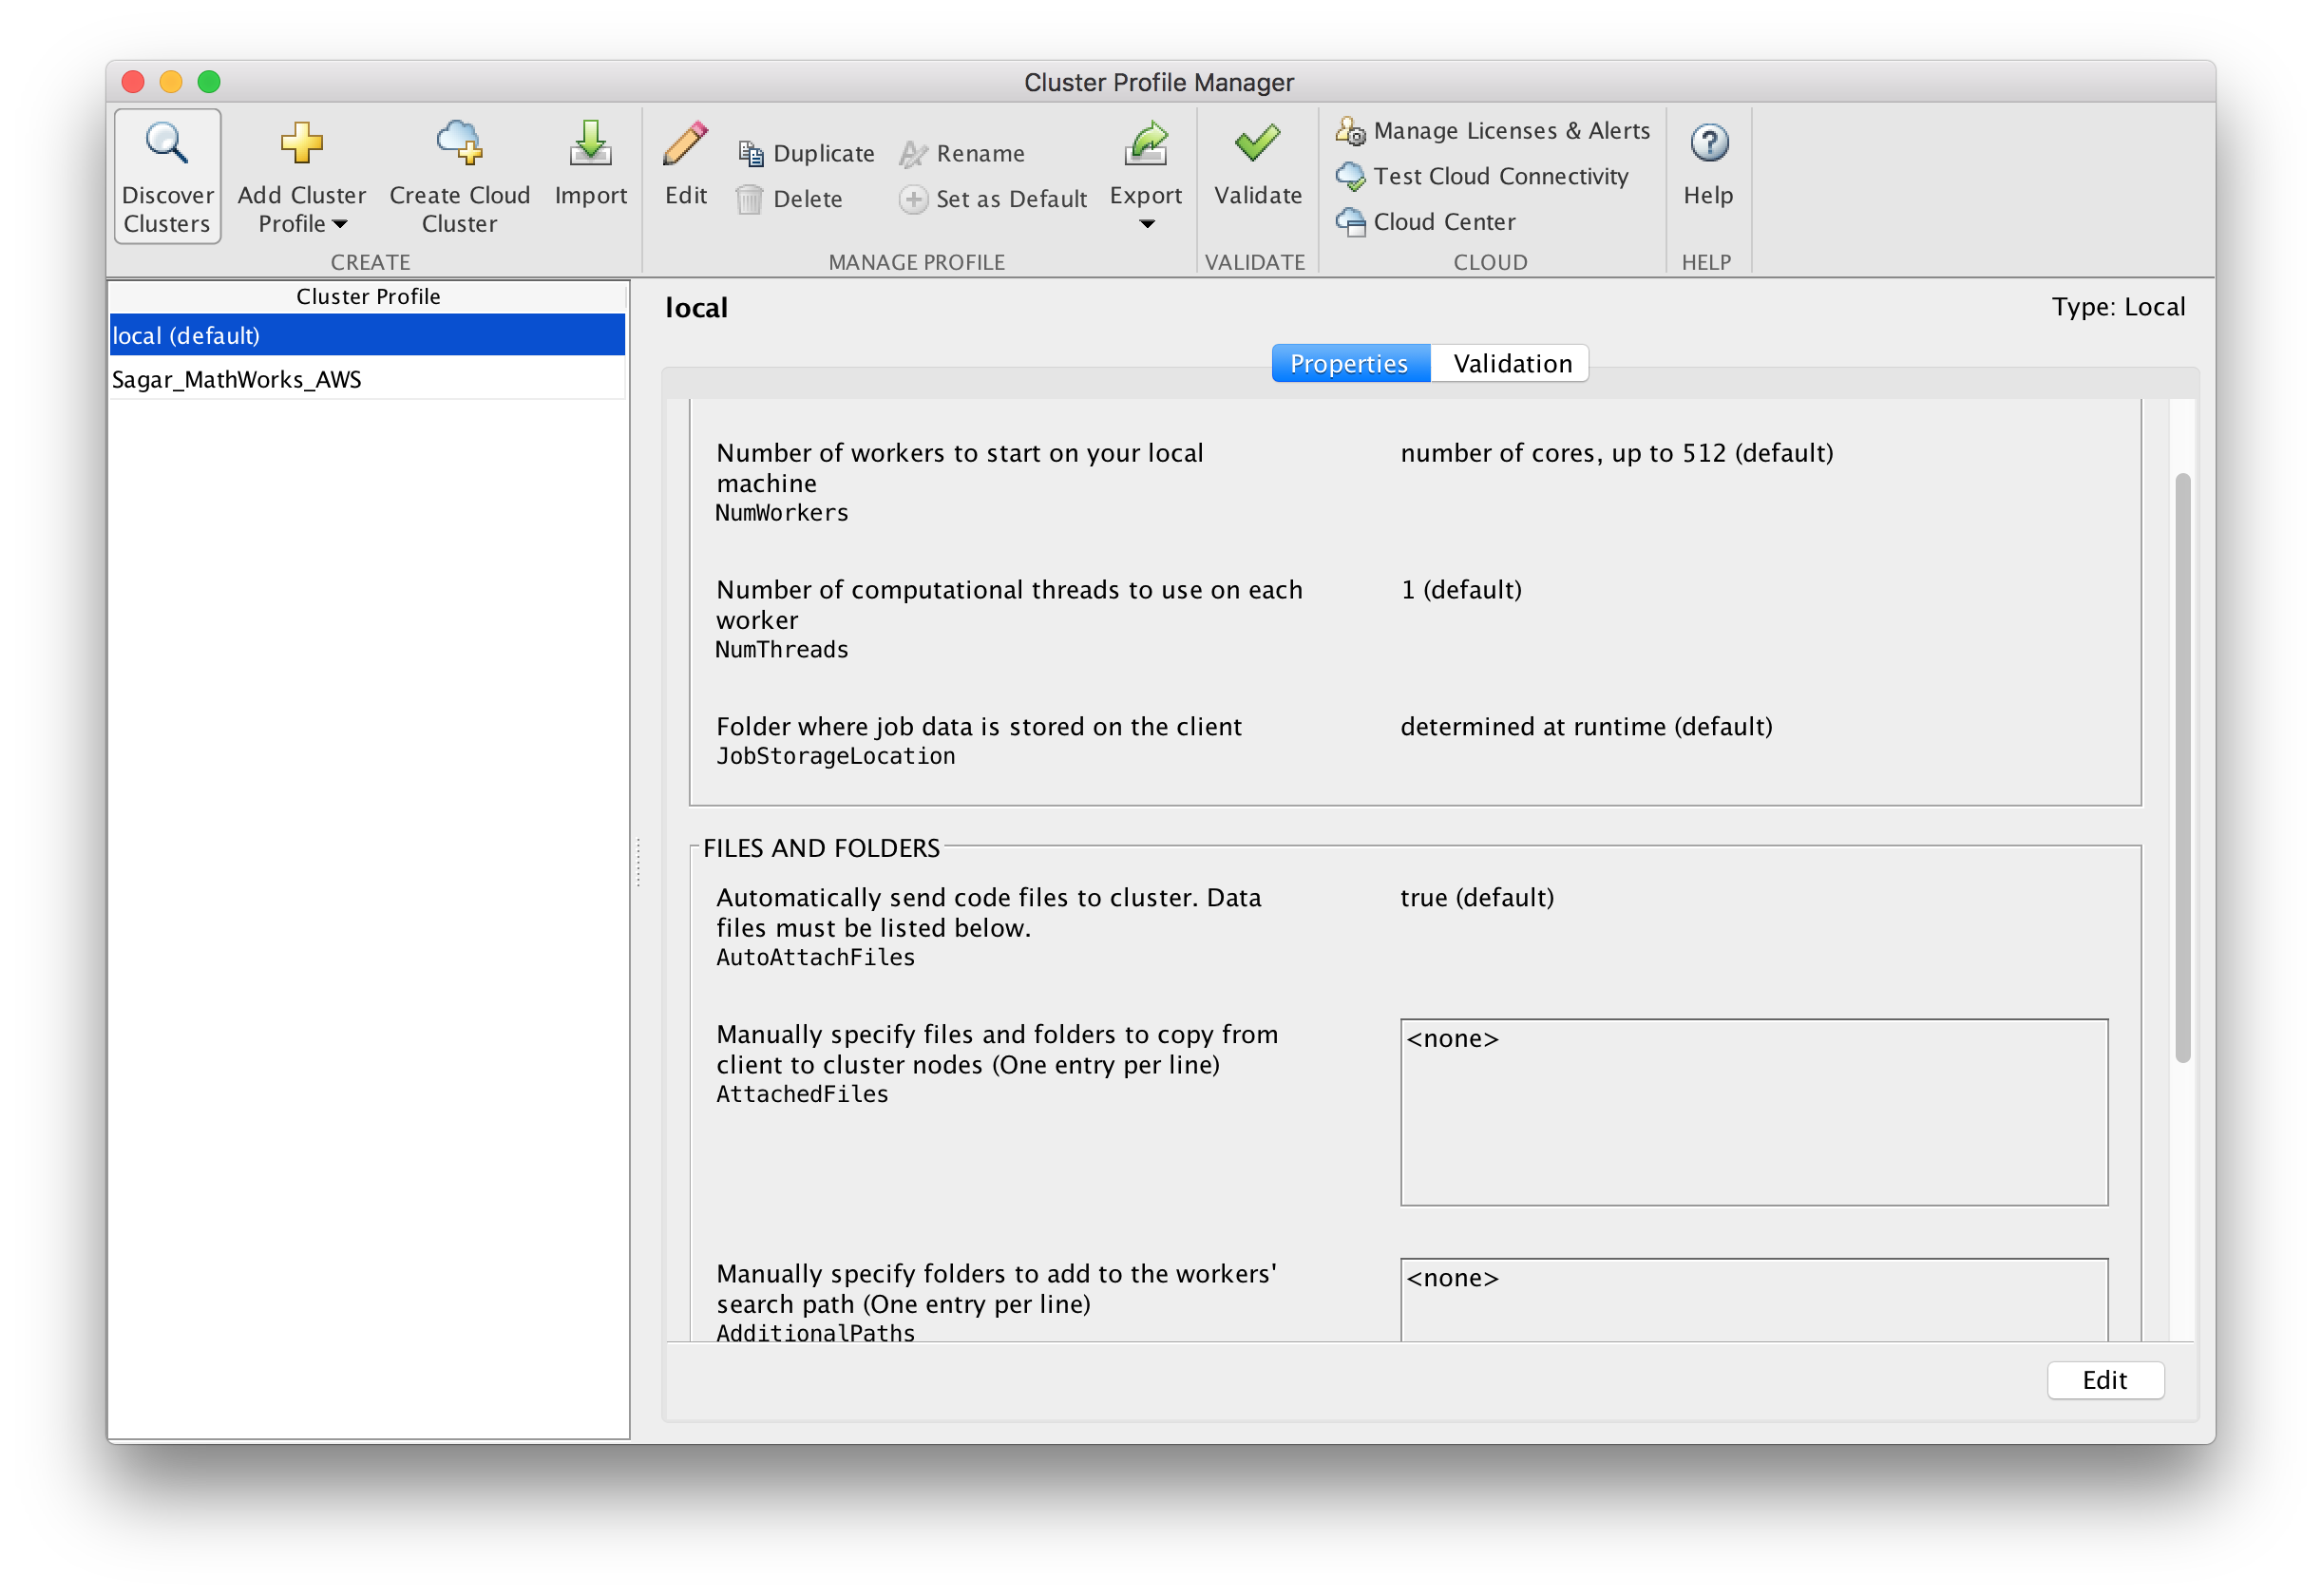

- Create a cluster using the `'local'` profile and name it `mylocal_cluster`

mylocal_cluster = parcluster('local')

mylocal_cluster = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: se-szade-m
                NumWorkers: 4
                NumThreads: 1

        JobStorageLocation: /Users/szade/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2020b
   RequiresOnlineLicensing: false

    

- Delete any existing pool

delete(gcp('nocreate'))

- Create a parellel pool inside `mylocal_cluster`.

pool_object = parpool(mylocal_cluster)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

pool_object = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 4
              Cluster: 

Take a look at the properties of the `mylocal_cluster`

## 3. Run cell segmentation without parallelization on my computer

- Create a directory to save the segmented images

save_path = 'Required files/segmented_files_no_parallel';
mkdir(save_path)

- Perform cell segmentation on 100 images and save them


tStart = tic;
for i = 1:1:200
    segment_and_save(['Required files/image_files/frame',num2str(i,'%03d'),'.tif'],save_path,i);
    disp(i)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



tEnd = toc(tStart);

- Display the time needed for the process of segmentation and saving images

disp(['Time elapsed with no parallelization = ',num2str(tEnd),' seconds'])

Time elapsed with no parallelization = 44.3116 seconds


## 4. Run cell segmentation with parallelization on my compter

- Create a directory to save the segmented images

save_path = 'Required files/segmented_files_parallel';
mkdir(save_path)

- Perform cell segmentation and save images

tStart = tic;
parfor i = 1:1:200
    segment_and_save(['Required files/image_files/frame',num2str(i, '%03d'),'.tif'],save_path,i);
    disp(i)
end

     3

     6

     9

    12

     8

     7

    11

    10

     2

     1

     5

     4

    36

    35

    60

    59

    84

    83

   108

   107

    34

    33

    58

    57

    82

    81

   106

   105

    32

    31

    56

    55

    80

    79

   104

   103

    30

    29

    54

    53

    78

    77

   102

   101

    28

    27

    52

    51

    76

    75

   100

    99

    26

    25

    50

    49

    74

    73

    98

    97

    48

    72

    96

    24

    47

    71

    95

    23

    22

    46

    70

    94

    45

    44

    69

    68

    93

    92

    21

    20

    19

    18

    43

    42

    67

    66

    91

    90

    41

    40

    65

    64

    89

    88

    17

    16

    15

    14

    39

    38

    63

    62

    61

    87

    86

    13

    37

    85

   156

   120

   144

   119

   118

   132

   131

   143

   142

   155

   154

   130

   129

   141

   140

   153

   152



tEnd = toc(tStart);

- Display the time needed for the process of segmentation and saving images

disp(['Time elapsed with parallelization = ',num2str(tEnd),' seconds'])

Time elapsed with parallelization = 36.5335 seconds


**Note that the code using parfor-loop ran faster than the for-loop. Also the order of execution is not regular. **

Additonal time is spend in transferring files to the MATLAB Workers. Hence the saving in time is not substantial. However, if you have many computationally intensive process on the same data, then the speed-up can be high. The problem is scalable when excecution speed increases in the proportion to the number of cores.

## 5. Run a script in the background - Submitting jobs

We will submit a MATLAB code to run as a job using the [`batch`](https://www.mathworks.com/help/parallel-computing/batch.html) command. A job is basically a container for tasks which should be run. 

This is a convenient way to run things that take a long time to run.

We can submit batch jobs from MATLAB to our **local computer **or the same workflow can be used to submit jobs to a **computer cluster** or the **cloud**.

### Submitting jobs to my computer

- The task is to combine the segmented images to form a video

Delete any existing parallel pool before we submit the job.

delete(gcp('nocreate'));

- Run the script `fountain_segmentation.m` as a job

frame_rate = 10;
filename = 'Required files/my_segmented_video';
imagefolder_datastore = imageDatastore('Required files/segmented_files_parallel');

job1 = batch(mylocal_cluster,@my_video_writer,1,{imagefolder_datastore,frame_rate,filename});

#### Check the state of the parallel job 

- Check the state programatically

job1.State

ans = 'running'

- We can also check the state interactively 

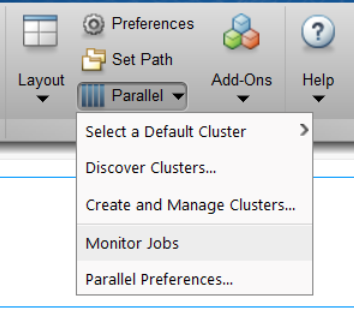

We can check that MATLAB is not blocked while the job is run in the background

Till the time the above operations are completed in the background, we can perform other calculations.

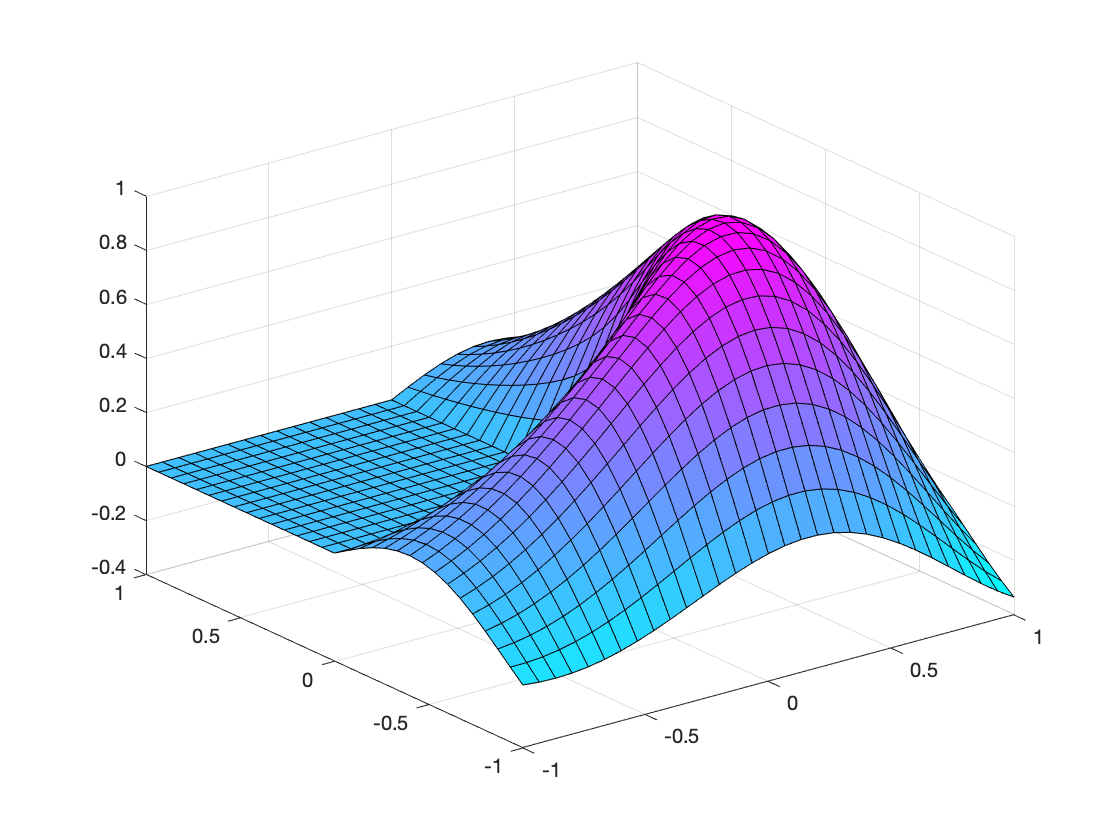

membrane()

Run some operation

1234567*9876543

ans = 1.2193e+13

Check the staus of the job

job1.State

ans = 'running'

Once the job is finished, we can either fetch the output of the job, or as in this case take a look at the video which is saved in the location `filename `

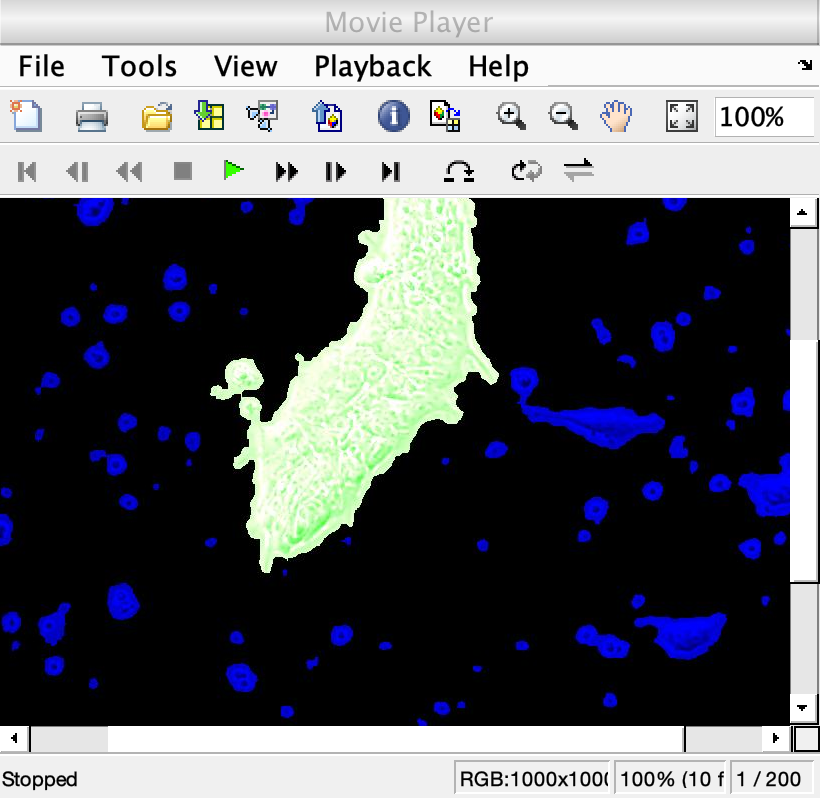

implay([filename,'.avi']);

#### Submit jobs interactively

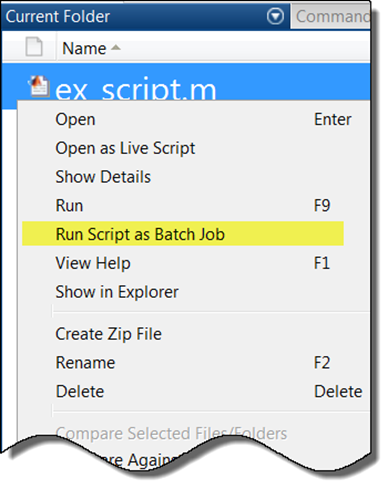

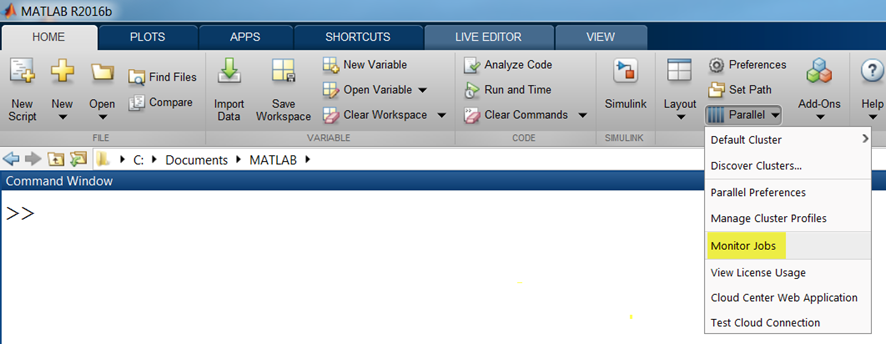

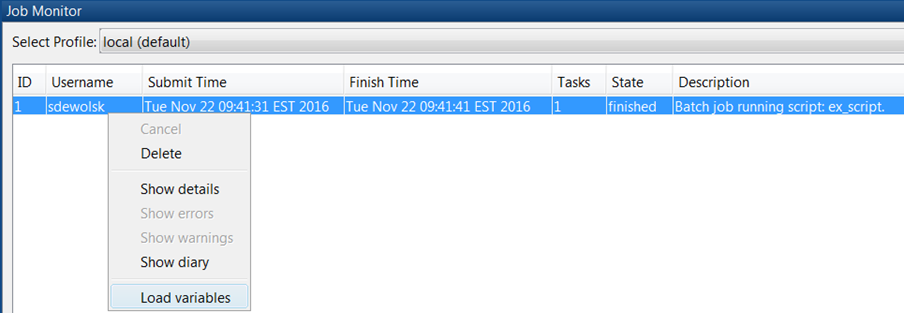

### Run your code on the cloud cluster

% myremote_cluster = parcluster('name_of_your_cloud_cluster');

% job_my_remote = batch(myremote_cluster,@my_video_writer,1,{imagefolder_datastore,frame_rate,filename});

## **6. Using GPUs**

### Run a computation on the GPU

- Check if my computer has a GPU?

% gpuDevice()

*Copyright 2020 The MathWorks, Inc*